# Proportional design using phase margins

This livescript is a brief manual in support of how to do proportional design using frequency response methods, or specifically, by managing the phase margin as viewed in a Bode diagram. The aim is to help users understand core principles and steps, afterwhich they may prefer to use ***sisotool*** or other means to undertake designs on systems of their own choosing.

A logical supporting file is ***proportional_design_with_bode.mlx*** which gives more comprehensive MATLAB source code and some examples. 

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help Control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Table of Contents

- Technical and mathematical background

- Simple gain design using phase margin criteria

- The design and operation of the app

## 1. Technical and mathematical background

This script assumes the following block diagram with system *G(s*) and compensator *M(s)*.

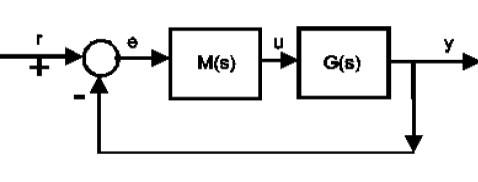

The closed-loop transfer function from target to output is:   $G_c =\frac{\textrm{GM}}{1+\textrm{GM}}$

This livescript assumes that:  $M\left(s\right)=K$

Frequency response design of M(s) focuses on the gain and phase margins as core indicators of likely closed-loop behaviour; however, it is only the phase margin that is used actively for proportional design. 

For more comprehensive background and code snippets, open the partner livescript file using the command below.

proportional_design_with_bode

Opening existing copy - delete or rename this copy to access toolbox orginal


## 2. Simple gain design using phase margin criteria

We want to design the gain of the compensator *M(s)* so that we have a desirable phase margin. This gives no control of the offset which may, as a consequence, be poor. The process can be systemised as follows.

- Decide desired PM and call this $\phi \ldotp$

- The PM is computed at the gain cross over frequency, so we can easily determine the frequency $w_c$ such that: $\arg \left(\textrm{GM}\right)=-180+\phi$. 

- Then chose the proportional K so that: $\left|\textrm{KG}\left(jw_c \right)\right|=1$

STEP 1: Data entry of *G(s)* and definition of target PM and production of base line bode diagram. For plotting purposes, the code below fixes  the frequency range so appropriate to the given *G(s)*. Change these values if required.

G=tf([1 1],[1 5 8 0]);
desiredPM = 50;
wmin=0.01;
wmax=100;

figure; clf
bode(G,{wmin,wmax});grid;hold on
plot([wmin,wmax],[-180+desiredPM]*[1 1],'r')
text(wmin*10,-180+desiredPM+10,'-180+\phi')


STEP 2: Enter the required cross over frequency $w_c$ on line below. **Make sure the green line crosses the intersect between the blue and red lines  on the open-loop bode plot.** Re-run section to update the plot.

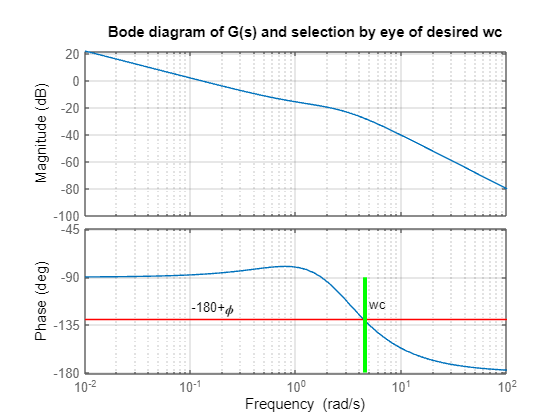

wc=4.5; %% Edit the wc value here

plot([wc,wc],[-180,-90],'g','linewidth',3)
text(wc*1.1,-180+desiredPM+15,'wc')
title(['Bode diagram of G(s) and selection by eye of desired wc'])

disp('*****************************************')

*****************************************


disp(['Identified a suitable wc as ',num2str(wc),'rad/s'])

Identified a suitable wc as 4.5rad/s


STEP 3: Determine the required gain *K* here automatically. If $w_c$ is computed correctly above, then the red compensated line will have $w_c$ as its gain cross over frequency, that is the intersect of the red and green line will be at 0dB. **Reminder that the phase diagram above is unchanged when we simply scale with a gain K.**

disp('*****************************************')

*****************************************


disp('Proportional design values')

Proportional design values


K=1/bode(G,wc)

K = 25.0085

K_in_DB = 20*log10(K)

K_in_DB = 27.9618

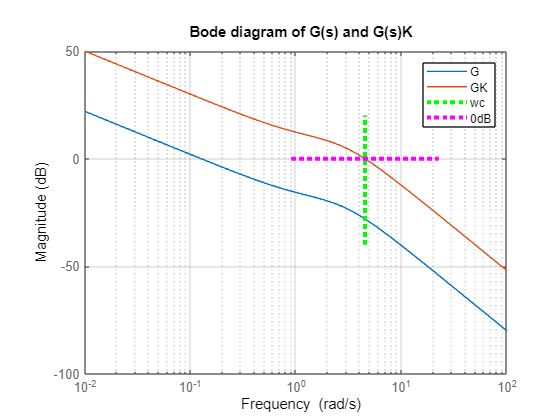


figure; clf
bodemag(G,G*K,{wmin,wmax});grid;hold on
plot([wc,wc],[-40,20],'g:','linewidth',3)
plot([wc/5,wc*5],[0,0],'m:','linewidth',3)
title(['Bode diagram of G(s) and G(s)K'])
legend('G','GK','wc','0dB')

disp('Margins with K chosen to meet PM criteria (approximately)')

Margins with K chosen to meet PM criteria (approximately)


disp(['Note how PM should closely match the target of ',num2str(desiredPM)])

Note how PM should closely match the target of 50


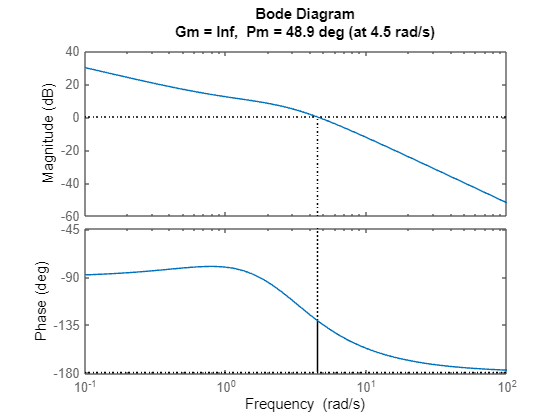

figure;clf
margin(G*K)

disp('BELOW is SECTION 3')

BELOW is SECTION 2


disp(' ');

## 3. The design and operation of the app

### 3.1 Choice of system and delay

The app has a number of pre-defined systems (1st, 2nd and 3rd order); the user can select one of these using the drop down menu. The most recent selection is the active choice and shown in the orange box in the bottom left. The app does not allow the user to make choices outside of those provided so in order to do this, the user would need to learn the principles and follow up in their own code, or for example, using sisotool. 

For interest, plots are given for the nominal system and also the system assuming there is some delay in the loop so users can visualise the impact of delay on the computations, bode diagrams and behaviour.

### 3.2 Figures and information displayed

The plots show the Bode diagrams (with and without the compensator $K_p$) alongside the target PM (pink dotted line) and the current gain cross-over frequency and current PM. They also show the compensated closed-loop responses (with and without delay).

The plots are updated automatically whenever the user interacts with the interface and thus changes:

- System choice

- Dead-time

- Desired PM

- Choice of gain

The principle is that the user can make incremental changes in the choice of gain $K_p$ and see how the PM and behaviour changes. To achieve the target PM, keep changing  $K_p$ until the pink dotted line in the phase subplot just touches/reachs the dashed green line (which is also where the blue line crosses the dashed green line).

**Remark**: For some systems the minimum phase is above -90 degrees and thus one can only achieve very high PM and the target PM may be a redundant feature.

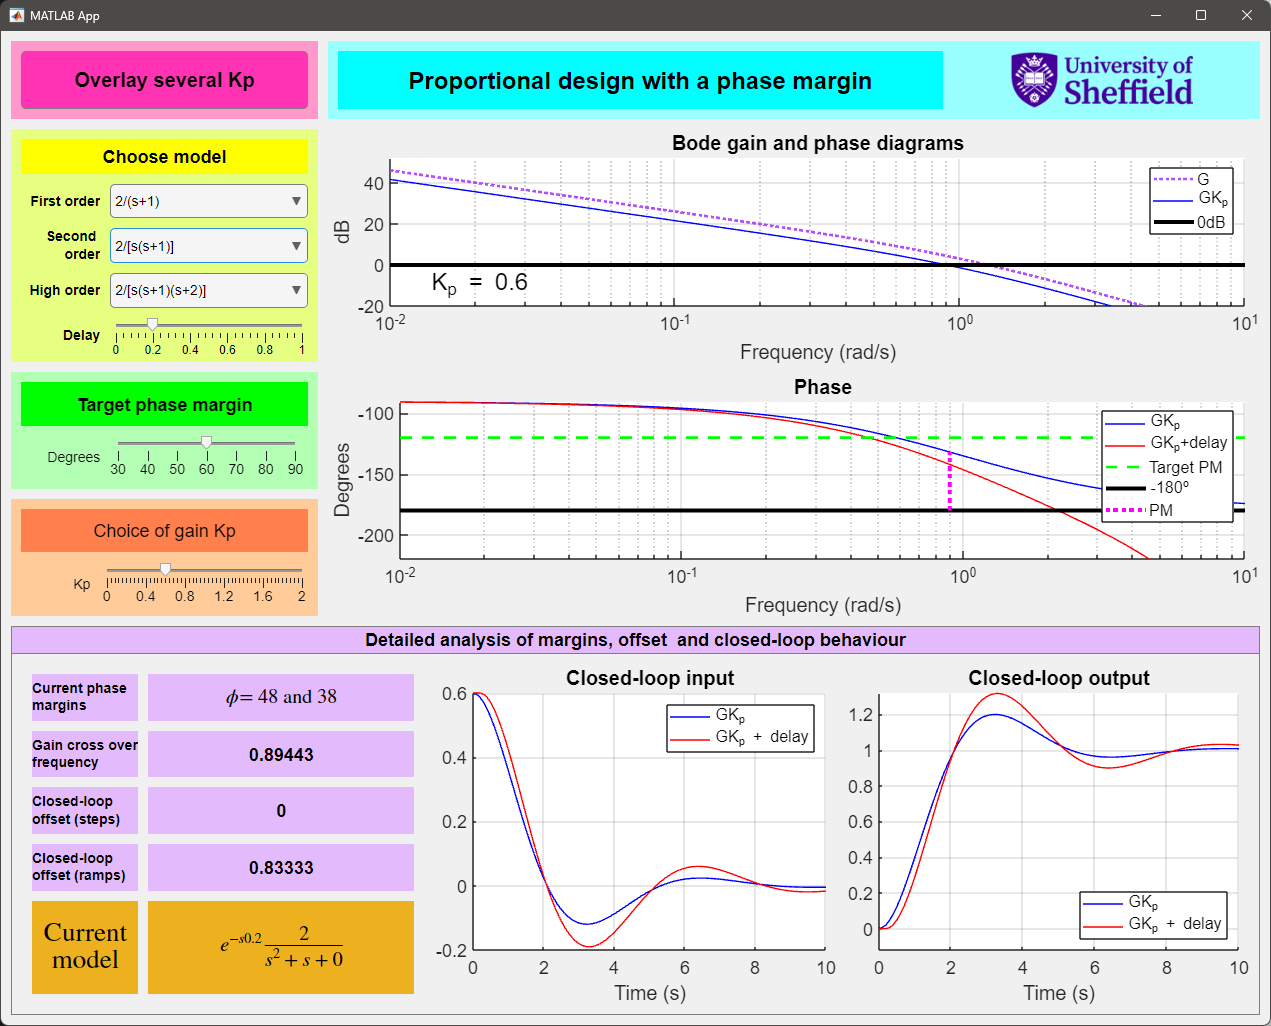

### 3.3 Overlay with alternative choices of proportional gain

It may be interesting to see how the PM and closed-loop behaviour changes for different choices of gain by plotting all the corresponding data simultaneously. The pink button in the top left will replace all the plots with overlays, but does so only for the nominal (undelayed) system. As soon as you select any other button, the plots revert to the original single choice of $K_p$.